Generating Graph

% clear previous variables
clear;


% ---------initial random graphs------------
% n=40; % nodes numbe
% e=1.1*n; % edges number
% G = graph(true(n), 'omitselfloops');
% p=randperm(numedges(G),e);
% G=graph(G.Edges(p,:));
% 
% %initial node positions
% nodePositions=randi(100,n,2);
% distance=nodePositions(:,1).^2+nodePositions(:,2).^2;
% [~,sortIndex]=sort(distance);
% nodePositions=nodePositions(sortIndex,sortIndex);
% 
% %plot graphs
% figure;
% plot(G,'XData', nodePositions(:,1), 'YData', nodePositions(:,2), 'NodeLabel', 1:n);
% hold on;
% 
% % Highlight the start node (assuming startNode is the ID of the start node)
% plot(nodePositions(1,1), nodePositions(1,2), 'go', 'MarkerSize', 10, 'LineWidth', 2);
% 
% % Highlight the goal node (assuming goalNode is the ID of the goal node)
% plot(nodePositions(n,1), nodePositions(n,2), 'ro', 'MarkerSize', 10, 'LineWidth', 2);
% 
% hold off;
% ^^^^^^^^^^^^^^^initial random graphs^^^^^^^^^^^^^

%---- Initial graphs -------
%preset node positions
nodes_positions=[-0.5	-0.5
    -0.09	-0.4
    -0.285	-0.305
    0.0575	-0.225
    -0.0525	-0.0175
    -0.37	0.3
    0.3525	-0.0525
    0.0625	0.255
    -0.1	0.3725
    0.4275	0.195
    0.345	0.3525
    0.5	0.5
    ];

% preset edges and costs
edges=[12	11	0.214
12	10	0.3135
12	8	0.5014
11	10	0.1778
11	9	0.4454
10	7	0.2586
9	8	0.2005
9	6	0.2796
9	5	0.5994
8	4	0.48
5	2	0.179
4	3	0.3517
4	2	0.2289
3	2	0.2169
3	1	0.2903
2	1	0.422
7	5	0.4402
5	4	0.11
];

G=graph(edges(:,1),edges(:,2),edges(:,3)); %the Graph
% suppossing starting node is 1, goal node is 12
star_node =1;
goal_node= 12;
%^^^^^^^^^^^ Initial graphs ^^^^^^^^

%-----------plot the graph------------
% plot the graph
plot(G,"XData",nodes_positions(:,1),"YData",nodes_positions(:,2),"LineWidth",3,"MarkerSize",10,"NodeFontSize",20,"EdgeLabel",G.Edges.Weight,"EdgeFontSize",15)

% mark start and goal nodes
hold on;
plot(nodes_positions(star_node,1),nodes_positions(star_node,2),'bo',"MarkerSize",15,"LineWidth",5);
plot(nodes_positions(goal_node,1),nodes_positions(goal_node,2),'ro',"MarkerSize",15,"LineWidth",5);

hold off;

% a function to plot the nodes
function plotnodes(nodeID,pos)
nodes_positions=pos;
hold on;
plot(nodes_positions(nodeID,1),nodes_positions(nodeID,2),'go',"MarkerSize",15,"LineWidth",5)
hold off;
end
%-^^^^^^^^^^plot the graph^^^^^^^^^^^^

% % --------Breadth First Search _ NO path-----------
% %step 1,2
% frontier={};% define the frontier nodes
% frontier{end+1}=star_node; % initial the start nodes as the first frontier
% reached=[]; % define reached nodes
% 
% %step 3
% while ~isempty(frontier)
% 
%     %step 4
%     current = frontier{1}; % add the first elements of frontier to current
%     frontier(1)=[]; % remove the first elements of frontier
% 
%     %plot the current nodes and denoted as green.
%     plotnodes(current,nodes_positions); 
% 
%     %step 5
%     %find the neighbors of current nodes
%     next_node=neighbors(G,current);
% 
%     %step 6
%     for i =1:length(next_node)
%         if ~ ismember(next_node(i),reached) % if neighbor nodes is not in the reached set
%             frontier{end+1}=next_node(i); % add neighbor nodes to frontier
%             reached=unique([next_node(i),reached]);  % add neighbor nodes to reached
%         end
% 
%     end
%     input('Press any key to continue...\n'); % waiting user's action, to show each explore step
% end
% 
% % ^^^^^^^^Breadth First Search  _ NO path^^^^^^^^^^^^

%--------Breadth First Search _ with path-----------
%step 1,2
frontier={};% define the frontier nodes
frontier{end+1}=star_node; % initial the start nodes as the first frontier
came_from=containers.Map('KeyType', 'double', 'ValueType', 'double'); % define reached nodes
came_from(1)=1;

%step 3
while ~isempty(frontier)

    %step 4
    current = frontier{1}; % add the first elements of frontier to current
    frontier(1)=[]; % remove the first elements of frontier

    %plot the current nodes and denoted as green.
    plotnodes(current,nodes_positions); 

    % if we find the goal, then exit the program.
    if current==goal_node
        break;
    end

    %step 5
    %find the neighbors of current nodes
    next_node=neighbors(G,current);

    %step 6
    for i =1:length(next_node)
        if ~ isKey(came_from,next_node(i)) % if neighbor nodes is not in the reached set
            frontier{end+1}=next_node(i); % add neighbor nodes to frontier
            came_from(next_node(i))=current;  % the value of dic is the last nodes
        end

    end
    % input('Press any key to continue...\n'); % waiting user's action, to show each explore step
end

% % print the map
% 
%     % Retrieve all keys
%     keySet = keys(reached);
% 
%     % Iterate through each key and print its corresponding value
%     disp('The map contains the following key-value pairs:');
%     for i = 1:length(keySet)
%         currentKey = keySet{i};
%         currentValue = reached(currentKey);
%         fprintf('%d: %d\n', currentKey, currentValue);
%     end

% extract path from map
path = [goal_node]

path = 12

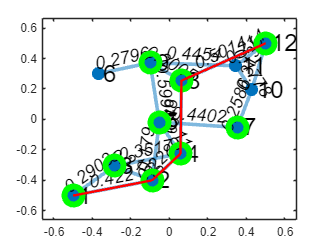

previous_node=came_from(goal_node);
while previous_node~=star_node
    path=[path previous_node];
    previous_node=came_from(previous_node);
end
path=[path star_node];

% ^^^^^^^^Breadth First Search  _ with path^^^^^^^^^^^^

%-------print the path on graph-----------------
hold on
plot(nodes_positions(path,1),nodes_positions(path,2),'r',"LineWidth",2);
hold off

%^^^^^^^print the path on graph^^^^^^^^^^^^^^^^^